# Sistema de telecomunicaciones digitales (16QAM Mod/Demod) - Laboratorio de sistemas de telecomunicaciones 2

**Universidad del Cauca - 2022-2**

**Entrega 1**

**Grupo 6 - Nicolás Zambrano y Sandy Suarez**

## Codificador

%------------------------------INICIO--------------------------------
clear;
tic;
Ro=0.35 ; U=16; L=8; Tf=1;
h1 = rcosfir(Ro, L, U, Tf,'sqrt') ; %Funcion de transferencia del filtro conformador de pulsos

%-------------------CONSTRUCCION DE MENSAJE------------------------
Ns=1000000; %número de bits
M=16; %orden de la modulación
Es=1; %este valor depende de la constelación
%vector de símbolos que entra al filtro conformador
msg=randsrc(1,Ns,[0 1]); %genera los bits a transmitir
for ind=1:1:32 %Ciclo iterativo para construir grafica de rendimiento
%--------CONSTRUCCION DE LOS SIMBOLOS------------
for i=1:4:length(msg)
    if msg(i)==0 && msg(i+1)==0 && msg(i+2)==0 && msg(i+3)==0
        simboloqam((i+3)/4)=0;
    elseif msg(i)==0 && msg(i+1)==0 && msg(i+2)==0 && msg(i+3)==1
        simboloqam((i+3)/4)=1;
    elseif msg(i)==0 && msg(i+1)==0 && msg(i+2)==1 && msg(i+3)==0
        simboloqam((i+3)/4)=2;
    elseif msg(i)==0 && msg(i+1)==0 && msg(i+2)==1 && msg(i+3)==1
        simboloqam((i+3)/4)=3;
    elseif msg(i)==0 && msg(i+1)==1 && msg(i+2)==0 && msg(i+3)==0
        simboloqam((i+3)/4)=4;
    elseif msg(i)==0 && msg(i+1)==1 && msg(i+2)==0 && msg(i+3)==1
        simboloqam((i+3)/4)=5;
    elseif msg(i)==0 && msg(i+1)==1 && msg(i+2)==1 && msg(i+3)==0
        simboloqam((i+3)/4)=6;
    elseif msg(i)==0 && msg(i+1)==1 && msg(i+2)==1 && msg(i+3)==1
        simboloqam((i+3)/4)=7;
    elseif msg(i)==1 && msg(i+1)==0 && msg(i+2)==0 && msg(i+3)==0
        simboloqam((i+3)/4)=8;
    elseif msg(i)==1 && msg(i+1)==0 && msg(i+2)==0 && msg(i+3)==1
        simboloqam((i+3)/4)=9;
    elseif msg(i)==1 && msg(i+1)==0 && msg(i+2)==1 && msg(i+3)==0
        simboloqam((i+3)/4)=10;
    elseif msg(i)==1 && msg(i+1)==0 && msg(i+2)==1 && msg(i+3)==1
        simboloqam((i+3)/4)=11;
    elseif msg(i)==1 && msg(i+1)==1 && msg(i+2)==0 && msg(i+3)==0
        simboloqam((i+3)/4)=12;
    elseif msg(i)==1 && msg(i+1)==1 && msg(i+2)==0 && msg(i+3)==1
        simboloqam((i+3)/4)=13;
    elseif msg(i)==1 && msg(i+1)==1 && msg(i+2)==1 && msg(i+3)==0
        simboloqam((i+3)/4)=14;
    elseif msg(i)==1 && msg(i+1)==1 && msg(i+2)==1 && msg(i+3)==1
        simboloqam((i+3)/4)=15;
    end
end
%-----------------MODULACION QAM----------------------
moduladaqam=qammod(simboloqam,16);
s=moduladaqam;
%-----------------------------------------------------
%-----------FILTRO CONFORMADOR DE PULSO---------------
% upsample 
su1=upsample(s,U);
%Agregacion de ceros al final del vector para evitar recorte por transiente
su=[su1 zeros(1,2*L*U)];
%Filtro de transmision
x1=filter(h1,1,su);
moduladaqam=x1;
%-----------------------------------------------------
%---------------------RUIDO---------------------------
%varianza=0;
ebno=1*ind; %EbNo en veces
Es=10; %Energia promedio de la constelacion
varianza=Es/(2*log2(M)*ebno);%determina la varianza de ruido
%Z=sigma*randn(1,length(S1)); %forma para dimensionar correctamente el ruido que se introduce al sistema 
ruidoqam=moduladaqam+((sqrt(varianza))*(randn(1,length(moduladaqam))+j*randn(1,length(moduladaqam))));
%snr=1.9;%Cambia la snr de la señal y el ruido (es funcion de la varianza)
%ruidoqam=awgn(moduladaqam,snr);
x1=ruidoqam;
%----------------------------------------
%------------FILTRO CONFORMADOR DE PULSO (RECONSTRUCCION)---------------
%Filtro de recepcion
x1=filter(h1,1,x1);
x1=x1(2*L*U+1:end);%Recorte del vector
s1=downsample(x1, U);
%s1=round(s1);
ruidoqam=s1;
%figure,
%plot(x1)
%-----------------------------------------------------
%------------RECONSTRUCCION DEL SIMBOLO---------------
demodqam=qamdemod(ruidoqam,16);
%-----------------------------------------------------
%-----------DEMODULACION QAM--------------
%demodqam=qamdemod(ruidoqam,16);%Desicion QAM
senalentrada=ruidoqam;
for i=1:1:length(senalentrada)
    if real(senalentrada(i))<=-2
        if imag(senalentrada(i))<=-2
            funsimb(i)=2;
        elseif imag(senalentrada(i))<=0
            funsimb(i)=3;
        elseif imag(senalentrada(i))<=2
            funsimb(i)=1;
        else
            funsimb(i)=0;
        end
    elseif real(senalentrada(i))<=0
        if imag(senalentrada(i))<=-2
            funsimb(i)=6;
        elseif imag(senalentrada(i))<=0
            funsimb(i)=7;
        elseif imag(senalentrada(i))<=2
            funsimb(i)=5;
        else
            funsimb(i)=4;
        end
    elseif real(senalentrada(i))<=2
        if imag(senalentrada(i))<=-2
            funsimb(i)=14;
        elseif imag(senalentrada(i))<=0
            funsimb(i)=15;
        elseif imag(senalentrada(i))<=2
            funsimb(i)=13;
        else
            funsimb(i)=12;
        end
    else
        if imag(senalentrada(i))<=-2
            funsimb(i)=10;
        elseif imag(senalentrada(i))<=0
            funsimb(i)=11;
        elseif imag(senalentrada(i))<=2
            funsimb(i)=9;
        else
            funsimb(i)=8;
        end
    end
end
demodqam=funsimb;
%-----------------------------------------------------
%-----------DECODIFICACION DE SIMBOLOS--------------
for i=1:1:length(demodqam)%Decodificacion Simbolos
    if demodqam(i)==0
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=0;
    elseif demodqam(i)==1
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=1;
    elseif demodqam(i)==2
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=0;
    elseif demodqam(i)==3
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=1;
    elseif demodqam(i)==4
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=0;
    elseif demodqam(i)==5
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=1;
    elseif demodqam(i)==6
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=0;
    elseif demodqam(i)==7
        bitqam((4*i)-3)=0;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=1;
    elseif demodqam(i)==8
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=0;
    elseif demodqam(i)==9
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=1;
    elseif demodqam(i)==10
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=0;
    elseif demodqam(i)==11
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=0;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=1;
    elseif demodqam(i)==12
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=0;
    elseif demodqam(i)==13
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=0;
        bitqam(4*i)=1;
    elseif demodqam(i)==14
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=0;
    elseif demodqam(i)==15
        bitqam((4*i)-3)=1;
        bitqam((4*i)-2)=1;
        bitqam((4*i)-1)=1;
        bitqam(4*i)=1;
    end
end
%----------------DETECCION DE ERRORES DE TRANSMISION---------------------
ser=nnz(~(demodqam == simboloqam));
vser(ind)=ser;
teober(ind)=((3/8)*erfc(sqrt((4/10)*ebno)));
ebnodb(ind)=10*log10(ebno);
end
t=toc

t = 8.1072

vber=vser./(Ns)%BER(casi igual a)SER debido a codificacion gray

vber =     0.1198    0.0711    0.0435    0.0268    0.0168    0.0103    0.0069    0.0042    0.0027    0.0017    0.0011    0.0007    0.0005    0.0003    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000         0         0


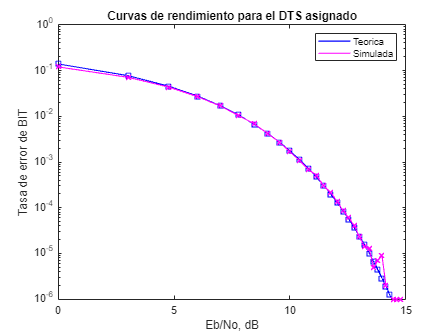

%------------------GRAFICA DE RENDIMIENTO---------------------
semilogy(ebnodb,vber)
close all; figure
semilogy(ebnodb,teober,'bs-','LineWidth',1);
hold on
semilogy(ebnodb,vber,'mx-','LineWidth',1);
axis([0 15 10^-6 1])
grid off
legend('Teorica', 'Simulada');
xlabel('Eb/No, dB')
ylabel('Tasa de error de BIT')
title('Curvas de rendimiento para el DTS asignado')

%------------------------------FIN--------------------------------